**Klasszikus ortogonális polinomok**

**Csebisev másodfajú polinom**


$$[-1; 1], \quad w(x) = \sqrt{1-x^2},\\
U_0(x) = 1, \quad U_1(x) = 2x,\\
U_{n+1}(x) =2x \cdot U_n(x) -U_{n-1}(x) \quad (n = 1, 2, . . .).$$



$$U_2(x) = 2x \cdot U_1(x) -U_0(x) = 4x^2-1
$$



$$U_3(x) =2 x \cdot U_2(x) - U_1(x) = 8x^3-2x-2x
=8x^3-4x
$$


N=5;
U=zeros(N+1,N+1);
Uef=zeros(N+1,N+1);
U(1,N+1)=1;
U(2,N)=2;
for k=2:N
U(k+1,1:N+1)=2*[U(k,2:N+1),0]-U(k-1,1:N+1);
end
U

U =      0     0     0     0     0     1
     0     0     0     0     2     0
     0     0     0     4     0    -1
     0     0     8     0    -4     0
     0    16     0   -12     0     1
    32     0   -32     0     6     0



for k=0:N
Uef(k+1,:)=U(k+1,:)/U(k+1,N-k+1);
end
Uef

Uef =          0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0    1.0000         0   -0.2500
         0         0    1.0000         0   -0.5000         0
         0    1.0000         0   -0.7500         0    0.0625
    1.0000         0   -1.0000         0    0.1875         0


Rajzoljuk ki az egy főegyütthatós Csebisev másodfajú polinomokat!

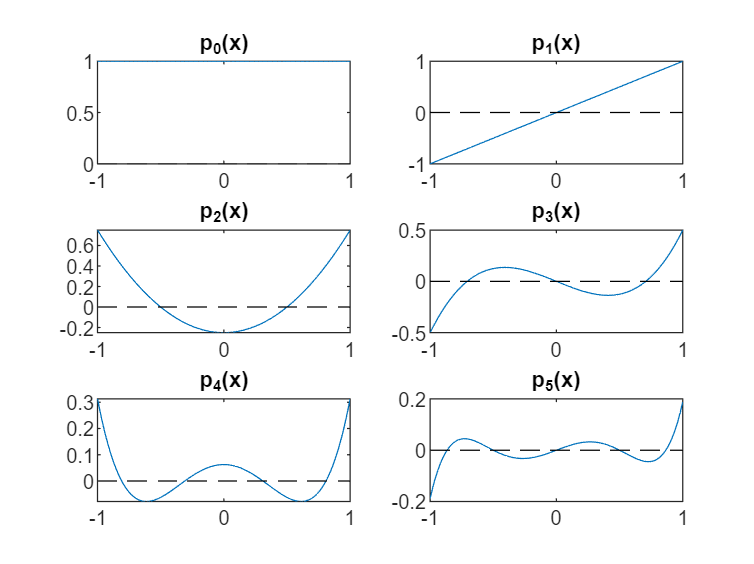

xx=linspace(-1,1,100);

for k=1:6
    subplot(3,2,k)
    pk=Uef(k,:);
    ppk=polyval(pk,xx);
    plot(xx,ppk,'-',xx,0*xx,'k--');
    title(sprintf('p_%d(x)',k-1));
end